# Cluster length distributions for Optical and Contact Clusters

## Investigate Length Distributions

Firstly, we want the counts of the clusters of length L, which is equivalent to dividing the imported data by the size of each cluster, since what we have here is the length of each cluster that each molecule occupies, which will be repeated N times where N is the size of the cluster that each molecule occupies.

A length of zero indicates a monomer and should be ignored.

fold = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/production_runs/250-02-100';
AAnames = {'250','500','750'};
AAparams = [2.5,5.,7.5];
SCnames = {'02','2','6','10'};
SCparams = [0.2,2,6,10];
Rnames = {'100','125','150','175'};
Rparams = [1,1.25,1.5,175];
runs = 5;
molno = 10648;
tsteps = 999;
cDistribs = zeros(tsteps,molno,runs);
oDistribs = zeros(tsteps,molno,runs);
oCIDs = zeros(tsteps,molno,runs);
cCIDs = zeros(tsteps,molno,runs);
tic
for run = 1:runs
    cDistribs(:,:,run) = importdata([fold '/mols10000_250-02-100_short_runldistrib' int2str(run) '_C.dat']);
    oDistribs(:,:,run) = importdata([fold '/mols10000_250-02-100_short_runldistrib' int2str(run) '_O.dat']);
    oCIDs(:,:,run) = importdata([fold '/mols10000_250-02-100_short_runcut0.35' int2str(run) 'optical-CIDs.dat']);
    cCIDs(:,:,run) = importdata([fold '/mols10000_250-02-100_short_runcut1.2225' int2str(run) 'contact-CIDs.dat']);
end
toc

Elapsed time is 176.566285 seconds.


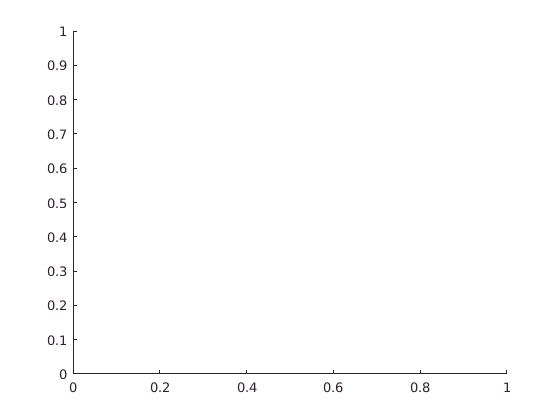

addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns');
colors = {};
c1 = [0 0.4470 0.7410];
c2 = [0.8500 0.3250 0.0980];
c3 = [0.9290 0.6940 0.1250];
c4 = [0.4940 0.1840 0.5560];
c5 = [0.4660 0.6740 0.1880];
c6 =  [0.3010 0.7450 0.9330];
c7 = [0.6350 0.0780 0.1840];
c8 = [0,0,0];
c9 = [1,0,0];
c10= [0,0,1];
cs = {c1,c2,c3,c4,c5,c6,c7,c8,c9,c10};
lcDistribs = cDistribs;
loDistribs = oDistribs;
lcDistribs(lcDistribs==0) = NaN;
loDistribs(loDistribs==0) = NaN;

%set(gca,'yscale','log')
%set(gca,'xscale','log')
cind = 1;
%for i = 99:100:999
i = 999;
binno = 50;

## Contact Cluster Histogram at Final Time

For comparison with fractal dimension data.

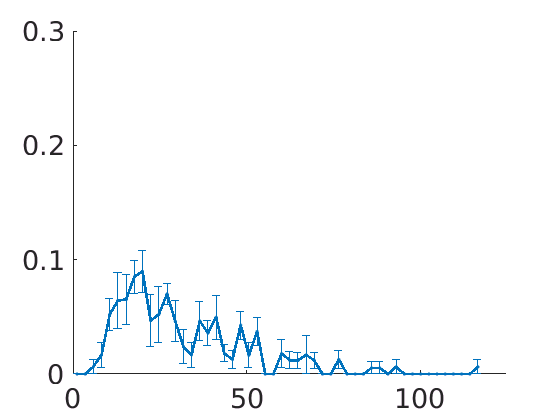

mx = 0;
cldis = {};
for run = 1:runs
    cldi = clDistrib(lcDistribs(i,:,run),cCIDs(i,:,run));
    mx = max(mx,max(cldi));
    cldis{run} = cldi;
end
edges = 0:(mx/binno):mx;
mids = (0.5*mx/binno):(mx/binno):mx;
rcounts = zeros(runs,binno);
for run = 1:runs
   rcounts(run,:) = histcounts(cldis{run},edges,'normalization','probability'); 
end
figure()
set(gca,'fontsize',20)
hold on
errorbar(mids,mean(rcounts),std(rcounts)/sqrt(5),'.','color',c1)
plot(mids,mean(rcounts),'linewidth',2,'color',c1)
ylim([0 0.3])
xlim([0,125])

%plot(mids,mean(rcounts),'x','markersize',20,'linewidth',3,'color',c1)
%histogram(cldi,10,'DisplayStyle','bar','edgecolor',cs{cind},'linewidth',2,'Normalization','probability');
    

## Optical Cluster Histogram at Final Time

For comparison with fractal dimension data.

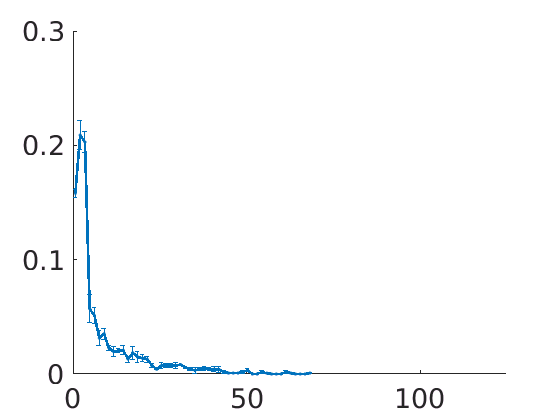

mx = 0;
oldis = {};
for run = 1:runs
    oldi = clDistrib(loDistribs(i,:,run),oCIDs(i,:,run));
    mx = max(mx,max(oldi));
    oldis{run} = oldi;
end
edges = 0:(mx/binno):mx;
mids = (0.5*mx/binno):(mx/binno):mx;
rcounts = zeros(runs,binno);
for run = 1:runs
   rcounts(run,:) = histcounts(oldis{run},edges,'normalization','probability'); 
end
figure()
set(gca,'fontsize',20)
hold on
errorbar(mids,mean(rcounts),std(rcounts)/sqrt(5),'.','color',c1)
plot(mids,mean(rcounts),'linewidth',2,'color',c1)
ylim([0 0.3])
xlim([0,125])

%plot(mids,mean(rcounts),'x','markersize',20,'linewidth',3,'color',c1)
%histogram(cldi,10,'DisplayStyle','bar','edgecolor',cs{cind},'linewidth',2,'Normalization','probability');
    

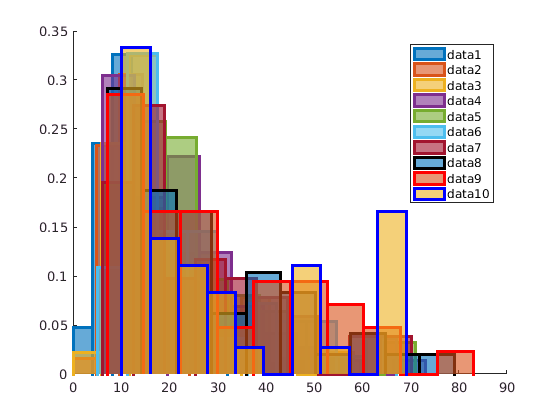

    %mids = (edges(1:(end-1)) + edges(2:end))/2;
    
    %plot(mids,H,'x','markersize',10,'color',cs{cind});
%    cind = cind + 1;
%end
%legend('data1','data2','data3','data4','data5','data6','data7','data8','data9','data10')

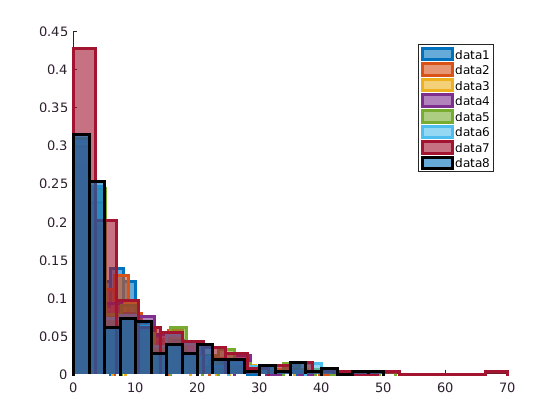


figure()
hold on
%set(gca,'yscale','log')
%set(gca,'xscale','log')
cind = 1;
for i = 99:100:799
    oldi = clDistrib(loDistrib(i,:),oCIDs(i,:));
    histogram(oldi,20,'DisplayStyle','bar','edgecolor',cs{cind},'linewidth',2,'Normalization','probability');
    
    %mids = (edges(1:(end-1)) + edges(2:end))/2;
    
    %plot(mids,H,'x','markersize',10,'color',cs{cind});
    cind = cind + 1;
end
legend('data1','data2','data3','data4','data5','data6','data7','data8','data9','data10')

We see that the distributions are, if not Gaussian, at least mostly half-Gaussian. Let us consider the change in the different moments over time: average length, mass-average length, and the infinite moment (maximum length):


$$\langle \Lambda \rangle_1 = \frac{\sum_iN_i \Lambda_i}{\sum_i N_i}$$



$$\langle\Lambda\rangle_2 = \frac{\sum_i N_i \Lambda_i^2}{\sum_i N_i \Lambda_i}$$



$$\langle \Lambda \rangle_\infty = \max_i(\Lambda_i)$$


addpath('/home/rachael/Analysis_and_run_code/data_visualization')
tic
cl1s = zeros(runs,tsteps);
cl2s = zeros(runs,tsteps);
clinfs = zeros(runs,tsteps);
ol1s = zeros(runs,tsteps);
ol2s = zeros(runs,tsteps);
olinfs = zeros(runs,tsteps);
for run = 1:runs
    [cl1,cl2,clinf] = lMoments(lcDistribs(:,:,run),cCIDs(:,:,run));
    [ol1,ol2,olinf] = lMoments(loDistribs(:,:,run),oCIDs(:,:,run));
    cl1s(run,:) = cl1;
    cl2s(run,:) = cl2;
    clinfs(run,:) = clinf;
    ol1s(run,:) = ol1;
    ol2s(run,:) = ol2;
    olinfs(run,:) = olinf;
end
toc

Elapsed time is 101.592336 seconds.


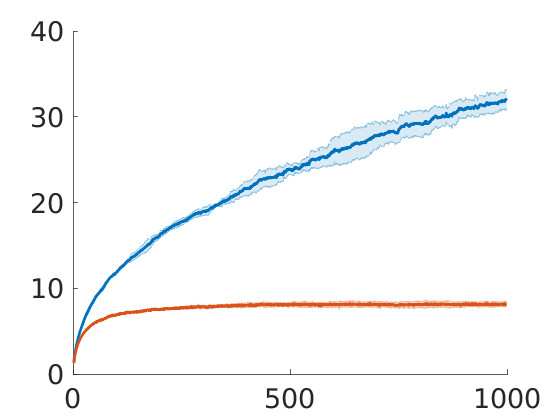

cl1mean = mean(cl1s);
cl2mean = mean(cl2s);
clinfmean = mean(clinfs);
ol1mean = mean(ol1s);
ol2mean = mean(ol2s);
olinfmean = mean(olinfs);
scl1mean = std(cl1s);
scl2mean = std(cl2s);
sclinfmean = std(clinfs);
sol1mean = std(ol1s);
sol2mean = std(ol2s);
solinfmean = std(olinfs);

cols = {[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.4940 0.1840 0.5560],[0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840],[0 0 0]};
lineProps = struct;
lineProps.col = cols;
lineProps.style = {'-','-','-','-','-','-','-','-'};

figure()
hold on
set(gca,'fontsize',20)
mseb(1:tsteps,[cl1mean; ol1mean],[scl1mean;sol1mean],lineProps);

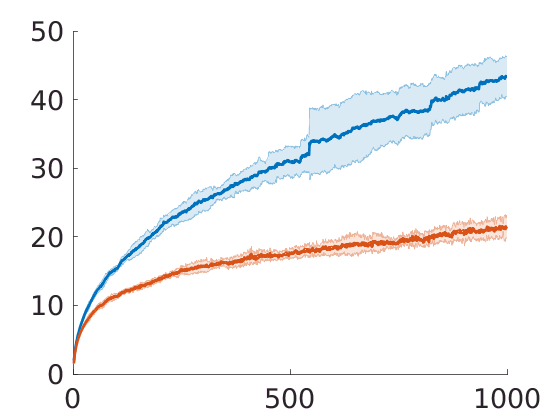


figure()
hold on
set(gca,'fontsize',20)
mseb(1:tsteps,[cl2mean; ol2mean],[scl2mean;sol2mean],lineProps);

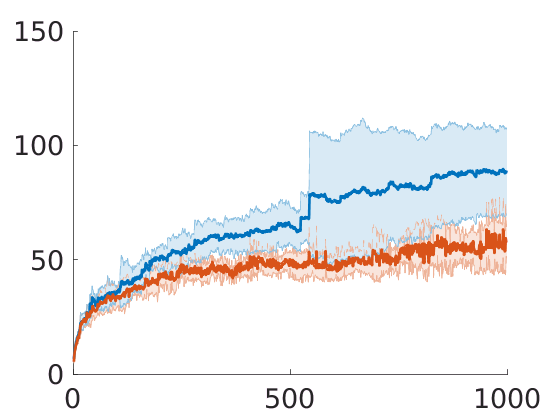


figure()
hold on
set(gca,'fontsize',20)
mseb(1:tsteps,[clinfmean; olinfmean],[sclinfmean;solinfmean],lineProps);